# Assignment 1: Steady Convection-Diffusion transport

## Introduction

Consider the one-dimensional convection-diffusion equation with Dirichlet boundary conditions on both ends:

  
$$\begin{cases}\displaystyle a\frac{du}{dx}-\nu \frac{d^2u}{dx^2}=s & \textrm{in} \ [0,1] \\
& \\
u(0)=u_D^{(0)} & \\
& \\
u(1)=u_D^{(1)}
\end{cases}$$


We can solve this problem through finite elements by calling the class 'SteadyConvectionDiffusionProblem'. However, we need to define some preliminar properties.

## Mesh set-up

We first define a 1D mesh composed of line elements. With the following lines we can define, for instance, a mesh consisting of 50 elements:

nEl           = 50;
xnode         = 0:1/nEl:1;
s.coord       = xnode';
s.connec(:,1) = 1:length(xnode)-1;
s.connec(:,2) = 2:length(xnode);
m             = Mesh.create(s)

m =   LineMesh with properties:

        geometryType: 'Line'
                type: 'LINE'
               kFace: 0
               coord: [51×1 double]
              connec: [50×2 double]
                ndim: 1
               nelem: 50
              nnodes: 51
           nnodeElem: 2
           coordElem: [1×2×50 double]
       interpolation: [1×1 Line_Linear]
               edges: []
               faces: []
       boundaryNodes: []
    boundaryElements: []


## Defining the Lagrangian function

Thus, we shall define the kind of interpolation that our finite element function will employ. Now, we will define a P1 FE function (linear interpolation) with empty coefficients. However, we could also define a P2 FE function (quadratic interpolation).

fieldDim = 1; % 1D
uTrial = LagrangianFunction.create(m,fieldDim,'P1');

## Dirichlet boundary conditions

We also need to define the left and right Dirichlet values, $u_D^{\left(0\right)}$ and $u_D^{\left(1\right)}$ respectively:

dir.left  = 0;
dir.right = 1;

## Source definition

Lastly, we can define analytically the source function as:

source = @(x) 10*exp(-5*x(1,:,:))-4*exp(-x(1,:,:));

## Solving the problem

Hence, we solve the whole problem by gathering all defined properties and calling the main class. Imagine that we would like to employ the original Galerkin formulation. Then we create:

s.mesh      = m;
s.trial     = uTrial;
s.sHandle   = source;
s.dirValues = dir;
s.stab      = 'Galerkin';
prob        = SteadyConvectionDiffusionProblem(s);

The solution can finally be obtained explicitly in function of the parameters $a$ and $\nu$.

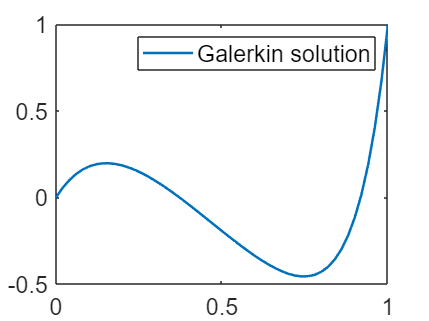

a  = 1;
nu = 0.1;
u  = prob.compute(a,nu);

## Questions

**1. The variable **$u$ **has a public property called fValues. Briefly describe which is the mathematical meaning of this property and its importance regarding the fundamentals of finite element methods.**

Write here your answer.

**2. Rewrite in the end of this script all the code together as a function of the inputs provided. Note that the Peclet number must be used as an input.**

**3. ..**

## **Auxiliar function definition**

function u = mainSteadyConvDif1D(nElem,order,dirLeft,dirRight,sHandle,stab,Pe)
a = 1;

% Write here your code...
end